# Example 4.1: Estimation for Gaussian RV using Moment-Matching

Note: this script reproduces Example 4.1 (Section 4.1.1) of **Statistics for Chemical Engineers**: estimating mu and sigma of a Gaussian from S = 10 and S = 100 observations. Victor Z UW-Madison, 2022 Gaussian moment example

clc; clear all; close all hidden;

## Few data (S = 10)

try few data points

S=10;

% generate data using true model
mu=1

mu =      1

sig=2

sig =      2

rng(1);
X=normrnd(mu,sig,S,1);

% use data to infer parameters using moment mathching
muhat=mean(X)

muhat =    4.5103e-01

sighat=std(X)

sighat =    1.4359e+00

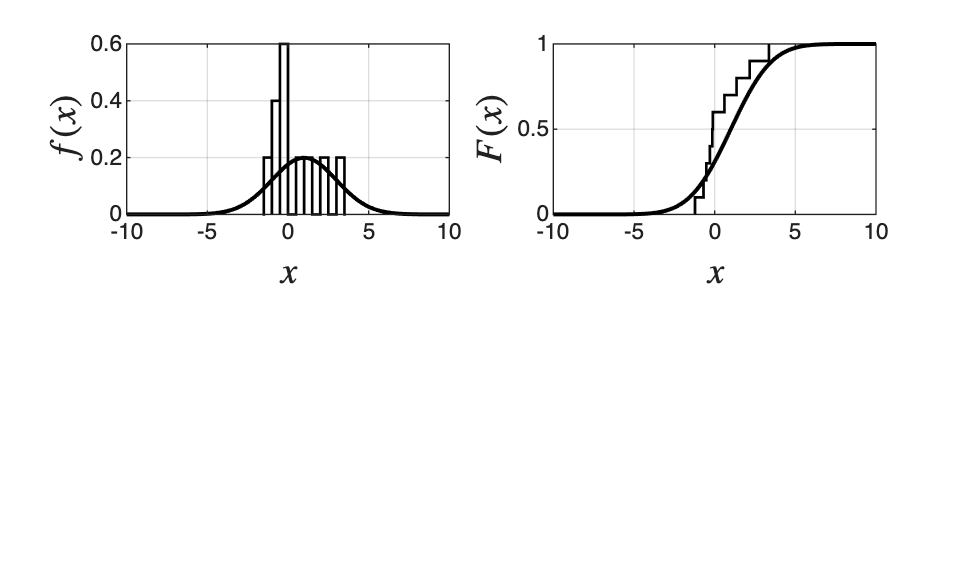



% compare truth against estima
subplot(2,2,1)
histogram(X,'BinWidth',0.5,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
x=linspace(-10,10,100);
plot(x,normpdf(x,mu,sig),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on

% compute and plot empirical cdf 
subplot(2,2,2)
[F,t]=ecdf(X);
stairs(t,F,'LineWidth',1,'Color','black')
hold on
plot(x,normcdf(x,mu,sig),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
grid on

## More data (S = 100)

try more data

S=100;
rng(1);
X=normrnd(mu,sig,S,1);

% use data to infer parameters using moment mathching
muhat=mean(X)

muhat =    9.0299e-01

sighat=std(X)

sighat =    1.9902e+00

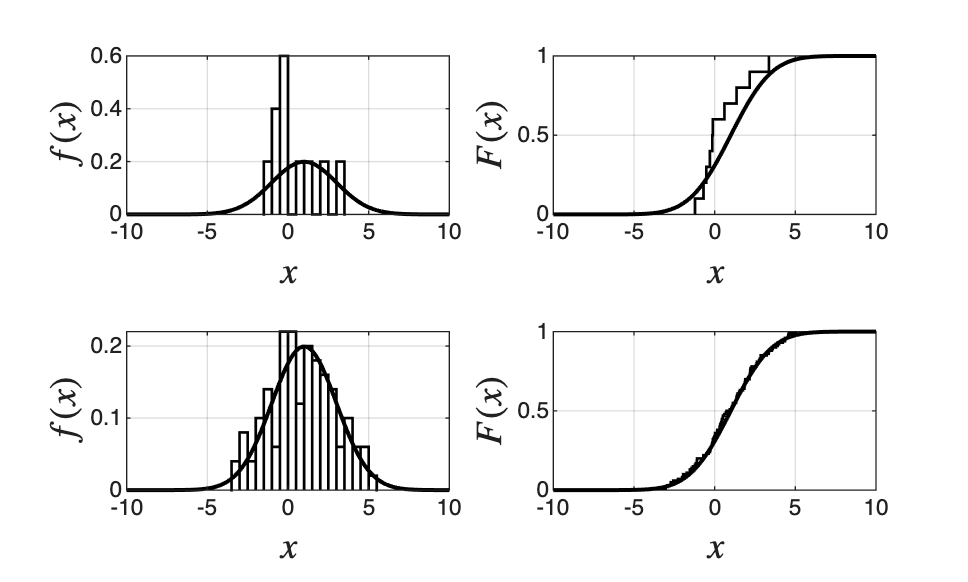


% compare truth against estima
subplot(2,2,3)
histogram(X,'BinWidth',0.5,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
plot(x,normpdf(x,mu,sig),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on

% compute and plot empirical cdf 
subplot(2,2,4)
[F,t]=ecdf(X);
stairs(t,F,'LineWidth',1,'Color','black')
hold on
plot(x,normcdf(x,mu,sig),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
grid on

print -depsc ch4_gaussian_moments_example.eps

## Note

As in the book, with S = 10 the model pdf/cdf cannot match the data well, while with S = 100 they match well and the data reveal the Gaussian nature of the phenomenon.